# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant and to make diagnosis

#### Select and read the data model file

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(4));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Diagnosis Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod,'Show',true);

Fuel Impact:          0.8320 (MW)
Technical Saving:     0.2459 (MW)


Diagnosis Summary - ECMP84

Key         MF(MW)      ΔI(MW)      ΔR(MW)     ΔPt(MW)     MF*(MW)     MR*(MW)    ΔPt*(MW)
———————————————————————————————————————————————————————————————————————————————————————————
COMB       -0.0254      0.2280      0.0000      0.0000      0.0200     -0.0408      0.0000
CMP         0.1691      0.2190      0.0000      0.0000      0.2784      0.0058      0.0000
TRB         0.0013      0.0340      0.0000      0.0000      0.0020     -0.0029      0.0000
APH        -0.0163     -0.0020      0.0000      0.0000     -0.0258     -0.0046      0.0000
HRSG        0.0069      0.1015      0.0000      0.2615      0.0110      0.0005      0.5883
STCK        0.0000      0.0000     -0.0100      0.0000      0.0000      0.0000      0.0000
ENV         0.1356      0.5805     -0.0100      0.2615      0.2856     -0.0419      0.5883


Malfunction Table (MW) - ECMP84

 key            COMB        CMP        TRB     

#### Show Graph Results

Show Default graph (Malfuncion Cost Table)

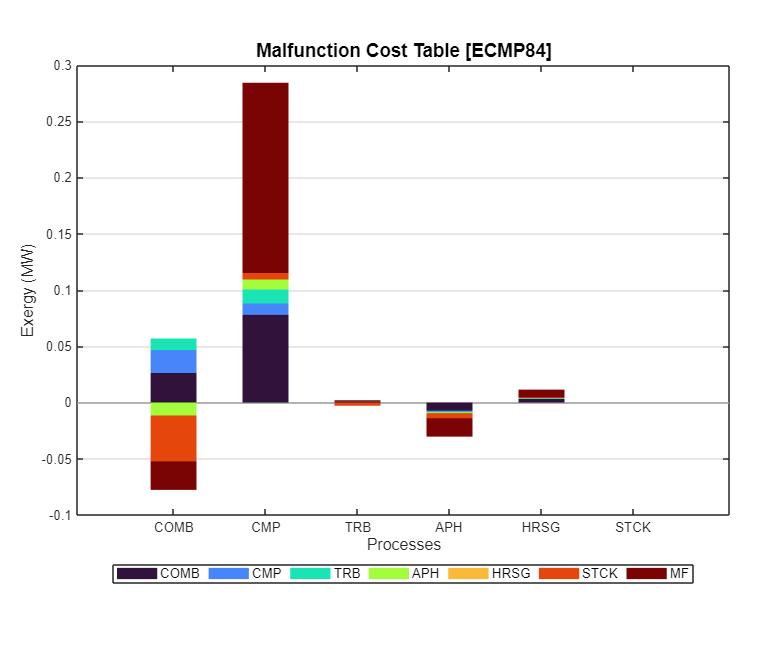

ShowGraph(res,'ShowOutput',false);

Show Total Malfunction Cost Graph

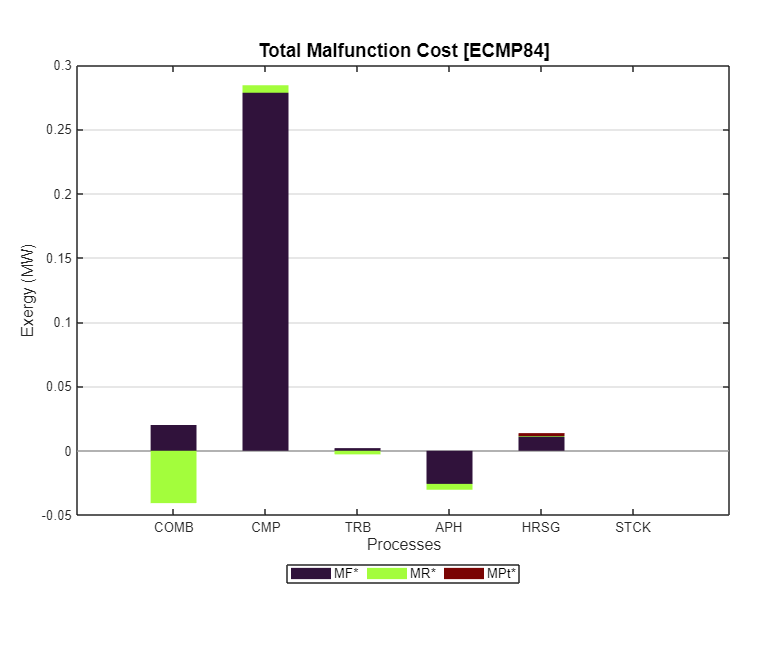

ShowGraph(res,'Graph','tmfc');

Show Fuel Impact graph

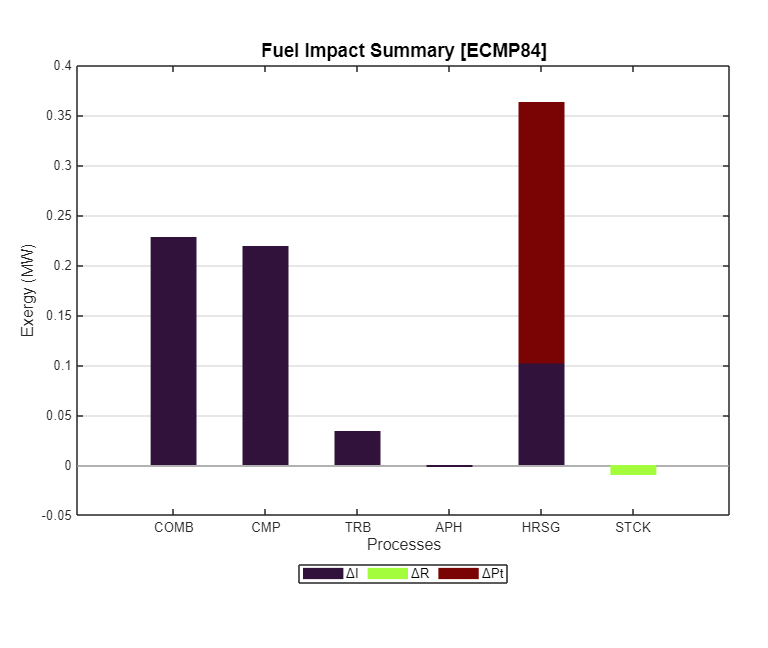

ShowGraph(res,'Graph','dft');

#### Additional Help

help ThermoeconomicDiagnosis

 ThermoeconomicDiagnosis - Compares two states of the plant and make a thermoeconomic diagnosis
    This function makes a thermoeconomic diagnosis of the plant, comparing two plant states. 
    Two different methods could be used to analyze the increase in waste generation: 
    'WASTE_EXTERNAL' accounts for the waste cost increase, and
    'WASTE_INTERNAL' internalises the waste costs to the productive processes that generate them. 
    The data model must have at least two states defined to perform the analysis.
  
    Syntax
 	  res = ThermoeconomicDiagnosis(data,Name,Value)
  
    Input Arguments
      data - cReadModel object containing the data information
     
    Name-Value Arguments
      Reference State - Reference State. If not provided first state is used
        char array
      State - State to compare. If not provided second state is used
        char array
      DiagnosisMethod - Select the method to compute diagnosis
        'WASTE_EX